load('C:\Users\mehul\Documents\PhD\REPOS_ONLINE\BMH_utils_matlab\DATA\fsLR_32k_facesAndVerts.mat')
load('C:\Users\mehul\Documents\PhD\REPOS_ONLINE\BMH_utils_matlab\DATA\fsLR_32k_Schaefer100-1000.mat')
dataModes = readmatrix('james-code_sphere_emodes_yeo_noMask.txt');



dataModes = dataModes(:,1:100);
% dataModes = [dataModes, zeros(size(dataModes, 1), 5)];

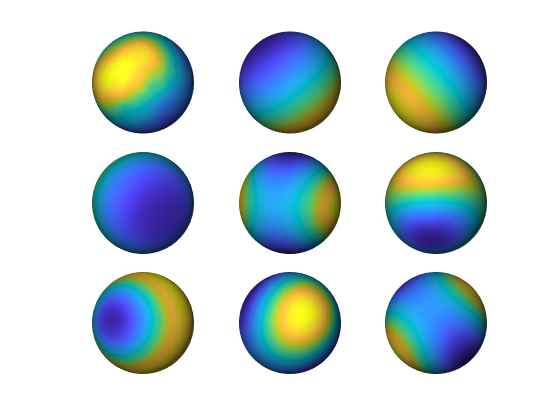


figure; 
plotBrain(lh_verts_sphere, lh_faces, ones(length(lh_verts_sphere),1), dataModes(:, 1:9));

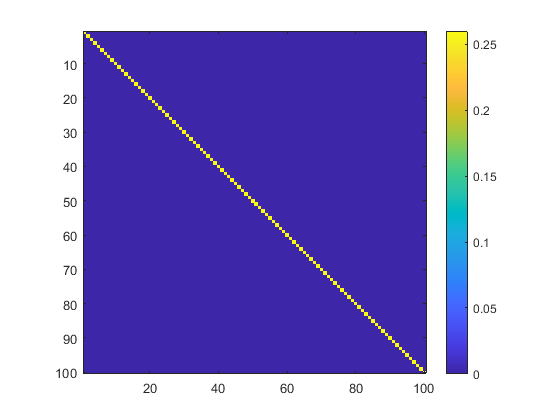


figure; 
imagescmode(dataModes.' * dataModes);

% 
% dataModes2 = dataModes;
% 
% for ii = 2:5
%     rot = makeRandomRotationMatrix(2*ii-1);
%     dataModes2(:, getEigengroupIdx(ii)) = dataModes(:, getEigengroupIdx(ii))*rot';
% end
% 
% figure; 
% plotBrain(lh_verts_sphere, lh_faces, ones(length(lh_verts_sphere),1), dataModes2);
% 
% 
% figure; 
% imagesc(dataModes2.' * dataModes2);


tic;
dataModes3 = eigenstrap(dataModes);
toc;

Elapsed time is 11.704178 seconds.


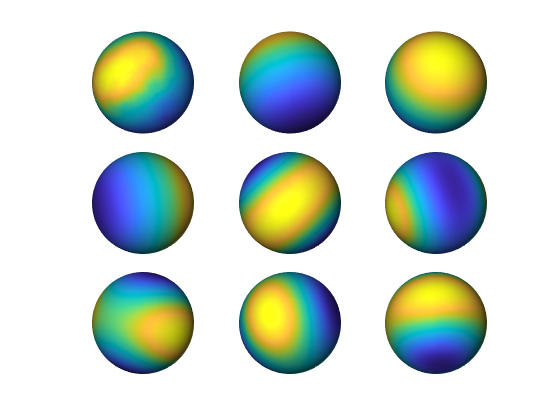


figure; 
plotBrain(lh_verts_sphere, lh_faces, ones(length(lh_verts_sphere),1), dataModes3(:,1:9));

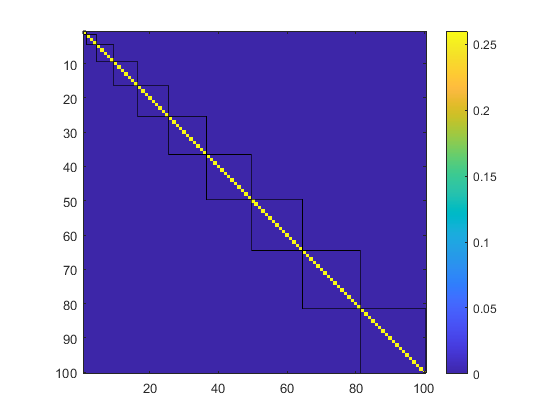



figure; 
imagescmode(dataModes3.' * dataModes3);

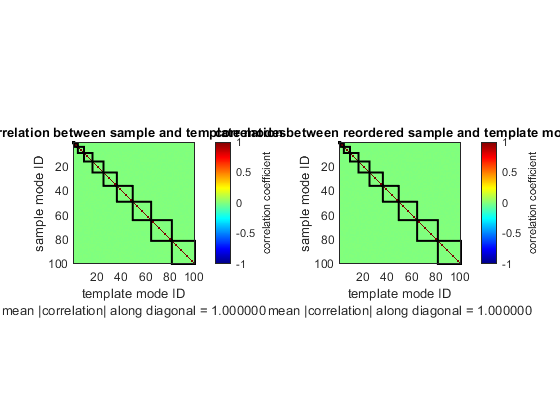


matchModes(dataModes3, dataModes, 'showFigures', 1);